# Time-Varying System Identification Using Adaptive Filters

**Objective: **To compare the performance of different Transform Domain LMS (TDL) convergence factors in tracking an unknown, time-varying system when the input signal is white or colored noise.

**Performance Analysis Summary**

Using the Mean-Square Error (MSE), the different convergence factor used had the following characteristic in the table below for both coloured and white noise input signal.

**Conclusion: **

Based on the MSE results, a convergence factor of 0.05 provided the best balance between convergence speed, tracking accuracy, and steady-state error. A convergence factor of 0.01 produced slower convergence and greater tracking lag, while a convergence factor of 1 was too large and caused divergence. Also, with the exception of the divergent case where μ = 1, the TD-LMS adaptive filter performed better in white-noise environments than in coloured-noise environments. This is because white noise has lower input correlation, allowing faster and more reliable adaptation, while coloured noise increases correlation and can slow convergence and reduce tracking accuracy.

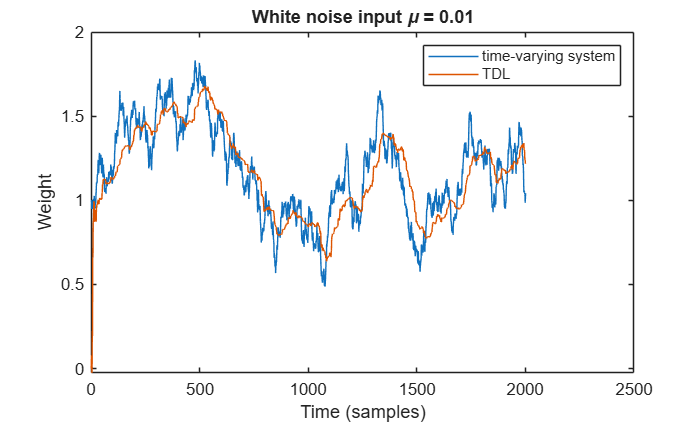

%% This script evaluates the performance of the DFT-LMS algorithm 
%% under various convergence factors for white and colored noise inputs.
%% DFT-LMS is a class of Transform Domain LMS (TD-LMS) adaptive filtering.



clear; clc;
 
h0 = [1 0.5 -2 0 -0.4]; % Unknown system, initial weights
M  = 5;                 % Adaptive Filter Length
mu = [0.01, 0.05, 1];   % Convergence constants
b  = 1;                 % time-varying system parameter
N  = 2000;        % samples per trial
numTrials = 50;   % ensemble size
sigma_v2 = 0.01;  % measurement noise variance
sigma_b2 = 0.001; % process noise variance (system drift)
lambda   = 0.06;  % power-estimate smoothing factor 
 
% DFT transform matrix F and diagonal shift matrix S
k = (0:M-1)';
m = 0:M-1;
F = (1/sqrt(M)) * exp(-2i*pi*(k*m)/M);
a = exp(-2i*pi*(0:M-1)/M);
S = diag(a);
 
% Lowpass filter for the colored-noise path
[Num, Den] = butter(10, 0.6);
 
% Theoretical MSE bound constants: 
Jmin = sigma_v2;
Ru   = eye(M);            % diag(ones(1,M))
Rb   = sigma_b2 * eye(M); % diag(sigma_b2*ones(1,M))
traceRu = trace(Ru);      % = M
traceRb = trace(Rb);      % = sigma_b2*M
 
% Preallocate ensemble-averaged error accumulators.
e_ensemble_lms       = zeros(length(mu), N);
e_ensemble_lms_color = zeros(length(mu), N);
 
%% ---- Main simulation ----
for q = 1:length(mu)
    for i = 1:numTrials
 
        % Generate white noise input and desired-signal noise.
        x = randn(1, N);
        v = sqrt(sigma_v2) * randn(1, N);
 
        % Generate colored noise by filtering white noise, then normalize
        % to unit variance.
        x_color = filter(Num, Den, x);
        x_color = x_color / std(x_color);
 
        % Resets time-varying system for this trial
        h = zeros(N+1, M);
        h(1,:) = h0;
 
        % Preallocate per-trial state (fixed size, no growing arrays).
        TLD_weights       = zeros(M, N+1);
        TLD_weights_color = zeros(M, N+1);
        xslide       = zeros(1, M);
        xslide_color = zeros(1, M);
        uvec       = zeros(1, M);
        uvec_color = zeros(1, M);
        xvec       = zeros(M, 1);
        xvec_color = zeros(M, 1);
        e       = zeros(1, N);
        e_color = zeros(1, N);
        d       = zeros(1, N);
        d_color = zeros(1, N);
        g  =  0.1;     % recursive power estimate, white-noise path
        p1 =  0.1;    % recursive power estimate, colored-noise path
 
        for j = 1:N
            % Time-varying unknown system .
            h(j+1,:) = b*h(j,:) + sqrt(sigma_b2)*randn(1, M);
 
            % Tapped-delay input vectors.
            xvec(2:M) = xvec(1:M-1);
            xvec(1)   = x(j);
            xvec_color(2:M) = xvec_color(1:M-1);
            xvec_color(1)   = x_color(j);
 
            % Desired signals.
            d(j)       = h(j+1,:)*xvec + v(j);
            d_color(j) = h(j+1,:)*xvec_color + v(j);
 
            % ---- White-noise DFT-LMS update ----
            p = xslide;
            xslide(2:M) = xslide(1:M-1);
            xslide(1)   = x(j);
            uvec = uvec*S + (1/sqrt(M))*(xslide(1)-p(M))*ones(1,M);
 
            g = lambda*mean(abs(uvec).^2) + (1-lambda)*g;
            e(j) = d(j) - uvec*TLD_weights(:,j);
            TLD_weights(:,j+1) = TLD_weights(:,j) + ...
             2*mu(q)/(0.001+g)*uvec'*e(j);
 
            % ---- Colored-noise DFT-LMS update ----
            p_color = xslide_color;
            xslide_color(2:M) = xslide_color(1:M-1);
            xslide_color(1)   = x_color(j);
            uvec_color = uvec_color*S + (1/sqrt(M))* ...
             (xslide_color(1)-p_color(M))*ones(1,M);
 
            p1 = lambda*abs(uvec_color(1))^2 + (1-lambda)*p1;
            e_color(j) = d_color(j) - uvec_color*TLD_weights_color(:,j);
            TLD_weights_color(:,j+1) = TLD_weights_color(:,j) + ...
                            2*mu(q)/(0.001+p1)*uvec_color'*e_color(j);
        end
 
        TLD_weights       = F*TLD_weights;
        TLD_weights_color = F*TLD_weights_color;
 
        e_ensemble_lms(q,:)       = e_ensemble_lms(q,:)       + e.^2;
        e_ensemble_lms_color(q,:) = e_ensemble_lms_color(q,:) + e_color.^2;
    end
 
    %% ---- Plots for this mu ----
    figure
    plot(1:N+1, h(:,1), 1:N+1, real(TLD_weights(1,:)))
    xlabel('Time (samples)'); ylabel('Weight');
    legend('time-varying system','TDL')
    title(['White noise input \mu = ' num2str(mu(q))]);
 
    figure
    plot(1:N+1, h(:,1), 1:N+1, real(TLD_weights_color(1,:)))
    xlabel('Time (samples)'); ylabel('Weight');
    legend('time-varying system','TDL')
    title(['coloured noise input \mu = ' num2str(mu(q))]);
 
    figure
    semilogy(1:N, real(e_ensemble_lms(q,:)/numTrials), ...
        1:N, real(e_ensemble_lms_color(q,:)/numTrials));
    title(['Ensembled averaged errors \mu = ' num2str(mu(q))]);
    xlabel('Time (samples)'); ylabel('Time-varying MSE');

  
    % Theoretical Mean Square Error.
    Jtheory = Jmin + mu(q)/2*sigma_v2*traceRu + 0.5/mu(q)*traceRb;
    line([0 N+1], [Jtheory Jtheory]);
    legend('White noise input','Coloured noise input', 'Theoretical');
end